## System Identification: NL model - Ham-weiner

Here we try to reconstruct the NL model of the system with Hammerstein-Weiner with step input.

step without mass

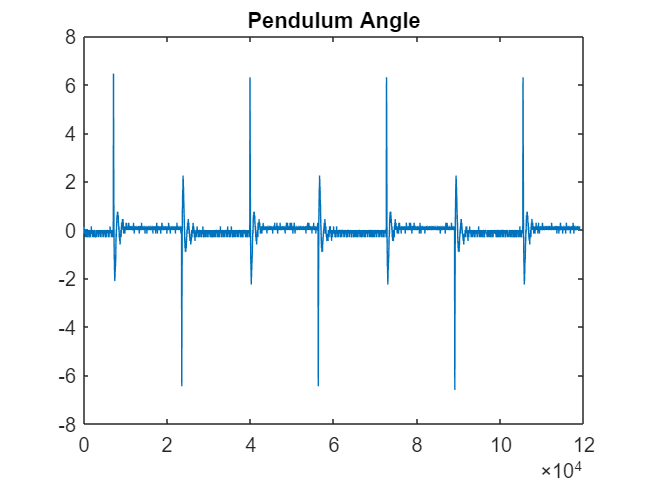

close all
clear

load("Edukit_Step Response Rotor Angle (degrees)__05-08-2023_17-35.mat")

plot(pendulum_angle);
title("Pendulum Angle")

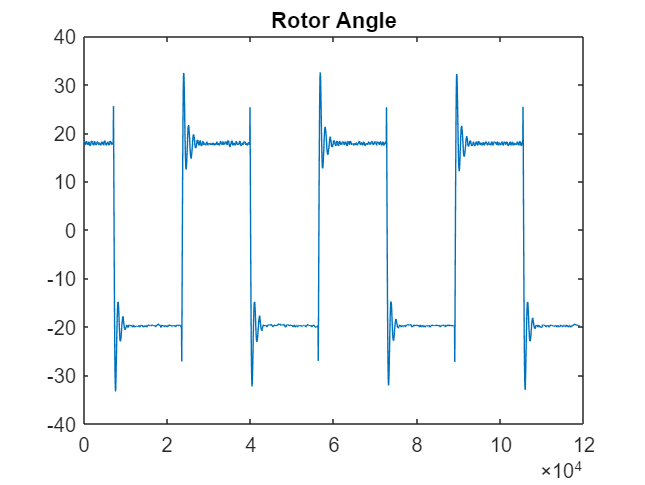


plot(rotor_angle);
title("Rotor Angle")

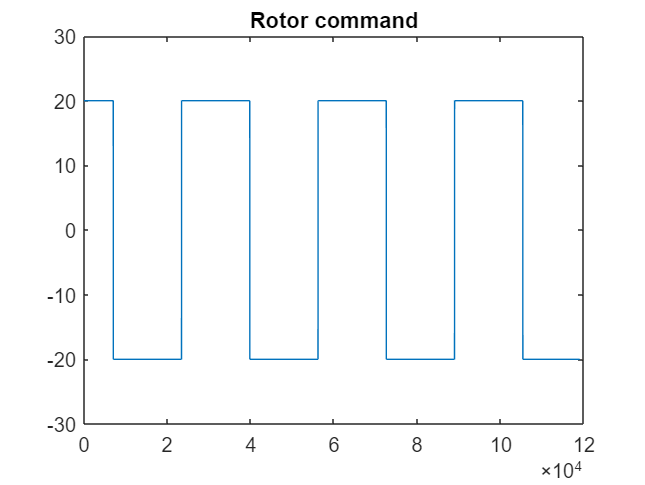


plot(rotor_command);
title("Rotor command")

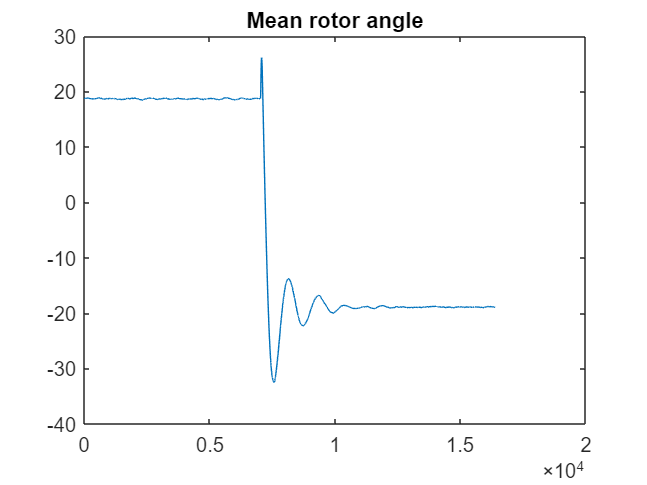


[mean_pendulum_angle]=calcola_media(pendulum_angle);
[mean_rotor_angle,t]=calcola_media(rotor_angle);

%calcola media computes the mean of a pendulum signal when a step is
%applied. It returns results in row

plot(mean_rotor_angle)
title("Mean rotor angle")

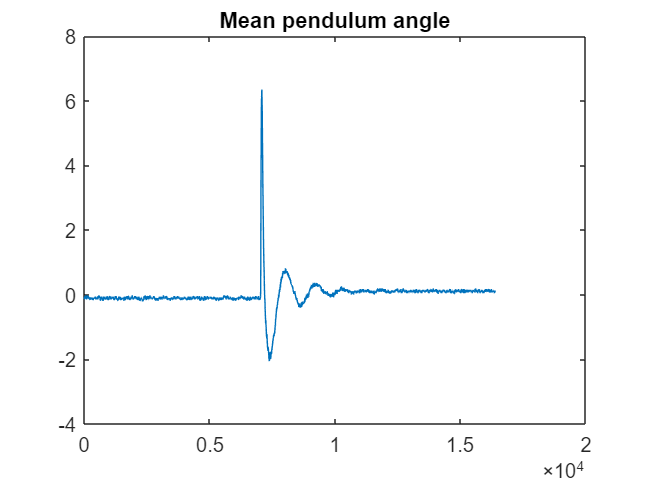


plot(mean_pendulum_angle)
title("Mean pendulum angle")

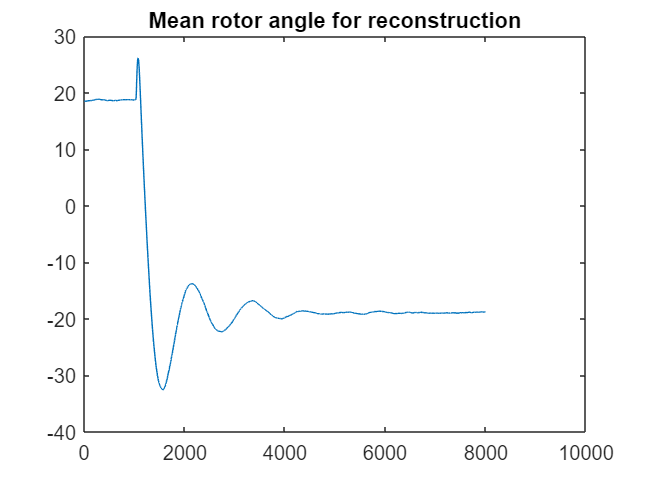


%Those are the ones for the reconstruction, just removed some useless part
%that the system identification was trying to replicate
mean_rotor_angle=mean_rotor_angle(6000:14000);
mean_pendulum_angle=mean_pendulum_angle(6000:14000);

plot(mean_rotor_angle)
title("Mean rotor angle for reconstruction")

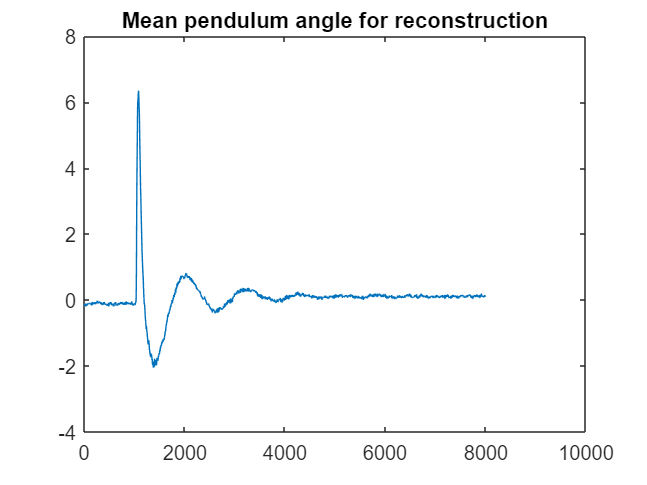



plot(mean_pendulum_angle)
title("Mean pendulum angle for reconstruction")

Best performance for ham-wein with **5 poles 2 zeros** and 3 breakpoints obtained with rotor angle between [0 40]. 

Otherwise with [-20 20] step input, the model doesn't reconstruct the correct dynamics.

PLOT DI SYSTEM OUTPUT NON FUNZIONA VEDILO DA ENRICO